clear all
load TR4_data.mat
syms t
syms q1(t) q2(t) q3(t)
syms Q1 Q2 Q3 Q1p Q2p Q3p
Q(1)=q1;
Q(2)=q2;
Q(3)=q3;
L=sym("l",[1 4]);
J=TR4_jacobian(Q,L);
Jp=diff(J,t)
Jp=subs(Jp,diff(q2),Q2p);
Jp=subs(Jp,diff(q1),Q1p);
Jp=subs(Jp,diff(q3),Q3p);
Jp=subs(Jp,q1,Q1);
Jp=subs(Jp,q2,Q2);
Jp=subs(Jp,q3,Q3)
Jp=matlabFunction(Jp)
detJ=det(J);
assume(Q,'positive')
simplify(detJ)
detJ=matlabFunction(detJ);
J=matlabFunction(J)

## calcolo Jacobiano

clear all
Q=sym("q",[1 3])

$$Q = \left(\begin{array}{ccc} q_{1} & q_{2} & q_{3} \end{array}\right)$$

L=sym("l",[1 4])

$$L = \left(\begin{array}{cccc} l_{1} & l_{2} & l_{3} & l_{4} \end{array}\right)$$

load TR4_data.mat
[M01_ M1_1 M12 M23]=TR4_positionMat(Q,L);
M01=M01_*M1_1;
M02=M01*M12;
M03=M02*M23;
S=M03*[0 0 0 1]'

$$S = \begin{array}{l} \left(\begin{array}{c} l_{2}+\frac{l_{3}}{2}+\frac{l_{3}\,\cos\left(q_{2}\right)}{2}+\sigma_{4}-\sigma_{3}-\sigma_{2}+\sigma_{1}\\ \frac{\sqrt{2}\,l_{3}\,\sin\left(q_{2}\right)}{2}+l_{4}\,\cos\left(q_{3}-\frac{\pi }{4}\right)\,\sin\left(q_{2}\right)\\ \frac{l_{3}}{2}-\frac{l_{3}\,\cos\left(q_{2}\right)}{2}-\sigma_{4}-\sigma_{3}-\sigma_{2}-\sigma_{1}\\ 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,l_{4}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}-\frac{\pi }{4}\right)}{2}\\ \sigma_{2}=\frac{\sqrt{2}\,l_{4}\,\sin\left(q_{3}-\frac{\pi }{4}\right)}{2}\\ \sigma_{3}=\frac{\sqrt{2}\,l_{1}\,\sin\left(q_{1}-\frac{\pi }{4}\right)}{2}\\ \sigma_{4}=\frac{\sqrt{2}\,l_{1}\,\cos\left(q_{1}-\frac{\pi }{4}\right)}{2} \end{array}$$

S=S(1:3)

$$S = \begin{array}{l} \left(\begin{array}{c} l_{2}+\frac{l_{3}}{2}+\frac{l_{3}\,\cos\left(q_{2}\right)}{2}+\sigma_{4}-\sigma_{3}-\sigma_{2}+\sigma_{1}\\ \frac{\sqrt{2}\,l_{3}\,\sin\left(q_{2}\right)}{2}+l_{4}\,\cos\left(q_{3}-\frac{\pi }{4}\right)\,\sin\left(q_{2}\right)\\ \frac{l_{3}}{2}-\frac{l_{3}\,\cos\left(q_{2}\right)}{2}-\sigma_{4}-\sigma_{3}-\sigma_{2}-\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,l_{4}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}-\frac{\pi }{4}\right)}{2}\\ \sigma_{2}=\frac{\sqrt{2}\,l_{4}\,\sin\left(q_{3}-\frac{\pi }{4}\right)}{2}\\ \sigma_{3}=\frac{\sqrt{2}\,l_{1}\,\sin\left(q_{1}-\frac{\pi }{4}\right)}{2}\\ \sigma_{4}=\frac{\sqrt{2}\,l_{1}\,\cos\left(q_{1}-\frac{\pi }{4}\right)}{2} \end{array}$$

J=jacobian(S,Q)

$$J = \begin{array}{l} \left(\begin{array}{ccc} -\sigma_{3}-\sigma_{2} & -\frac{l_{3}\,\sin\left(q_{2}\right)}{2}-\sigma_{4} & -\sigma_{5}-\sigma_{1}\\ 0 & l_{4}\,\cos\left(q_{2}\right)\,\sigma_{6}+\frac{\sqrt{2}\,l_{3}\,\cos\left(q_{2}\right)}{2} & -l_{4}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}-\frac{\pi }{4}\right)\\ \sigma_{2}-\sigma_{3} & \frac{l_{3}\,\sin\left(q_{2}\right)}{2}+\sigma_{4} & \sigma_{1}-\sigma_{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,l_{4}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}-\frac{\pi }{4}\right)}{2}\\ \sigma_{2}=\frac{\sqrt{2}\,l_{1}\,\sin\left(q_{1}-\frac{\pi }{4}\right)}{2}\\ \sigma_{3}=\frac{\sqrt{2}\,l_{1}\,\cos\left(q_{1}-\frac{\pi }{4}\right)}{2}\\ \sigma_{4}=\frac{\sqrt{2}\,l_{4}\,\sigma_{6}\,\sin\left(q_{2}\right)}{2}\\ \sigma_{5}=\frac{\sqrt{2}\,l_{4}\,\sigma_{6}}{2}\\ \sigma_{6}=\cos\left(q_{3}-\frac{\pi }{4}\right) \end{array}$$

detJ=det(J);

J=matlabFunction(J)

J = function_handle with value:
    @(l1,l3,l4,q1,q2,q3)reshape([sqrt(2.0).*l1.*cos(q1-pi./4.0).*(-1.0./2.0)-(sqrt(2.0).*l1.*sin(q1-pi./4.0))./2.0,0.0,sqrt(2.0).*l1.*cos(q1-pi./4.0).*(-1.0./2.0)+(sqrt(2.0).*l1.*sin(q1-pi./4.0))./2.0,l3.*sin(q2).*(-1.0./2.0)-(sqrt(2.0).*l4.*cos(q3-pi./4.0).*sin(q2))./2.0,l4.*cos(q2).*cos(q3-pi./4.0)+(sqrt(2.0).*l3.*cos(q2))./2.0,(l3.*sin(q2))./2.0+(sqrt(2.0).*l4.*cos(q3-pi./4.0).*sin(q2))./2.0,sqrt(2.0).*l4.*cos(q3-pi./4.0).*(-1.0./2.0)-(sqrt(2.0).*l4.*cos(q2).*sin(q3-pi./4.0))./2.0,-l4.*sin(q2).*sin(q3-pi./4.0),sqrt(2.0).*l4.*cos(q3-pi./4.0).*(-1.0./2.0)+(sqrt(2.0).*l4.*cos(q2).*sin(q3-pi./4.0))./2.0],[3,3])


## Calcolo Jacobiano punto

clear all
load TR4_data.mat
syms t
syms q1(t) q2(t) q3(t)
syms Q1 Q2 Q3 Q1p Q2p Q3p
Q(1)=q1;
Q(2)=q2;
Q(3)=q3;
L=sym("l",[1 4]);
J=TR4_jacobian(Q,L);
Jp=diff(J,t)

Jp=subs(Jp,diff(q2),Q2p);
Jp=subs(Jp,diff(q1),Q1p);
Jp=subs(Jp,diff(q3),Q3p);
Jp=subs(Jp,q1,Q1);
Jp=subs(Jp,q2,Q2);
Jp=subs(Jp,q3,Q3)

$$Jp = \begin{array}{l} \left(\begin{array}{ccc} -\mathrm{Q1p}\,l_{1}\,\cos\left(Q_{1}\right) & \sigma_{1}-\sigma_{8}-\sigma_{6}-\sigma_{3}-\sigma_{11} & \sigma_{9}-\sigma_{10}-\sigma_{7}-\sigma_{5}-\sigma_{4}+\sigma_{2}\\ 0 & \mathrm{Q3p}\,l_{4}\,\cos\left(Q_{2}\right)\,\sigma_{13}-\frac{\mathrm{Q2p}\,\sin\left(Q_{2}\right)\,\left(\sqrt{2}\,l_{3}+2\,l_{4}\,\sigma_{12}\right)}{2} & \mathrm{Q2p}\,l_{4}\,\cos\left(Q_{2}\right)\,\sigma_{13}-\mathrm{Q3p}\,l_{4}\,\sin\left(Q_{2}\right)\,\sigma_{12}\\ \mathrm{Q1p}\,l_{1}\,\sin\left(Q_{1}\right) & \sigma_{11}+\sigma_{8}+\sigma_{6}+\sigma_{3}-\sigma_{1} & \sigma_{9}-\sigma_{10}+\sigma_{7}+\sigma_{5}+\sigma_{4}-\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{Q3p}\,l_{4}\,\sin\left(Q_{2}\right)\,\sin\left(Q_{3}\right)}{2}\\ \sigma_{2}=\frac{\mathrm{Q2p}\,l_{4}\,\sin\left(Q_{2}\right)\,\sin\left(Q_{3}\right)}{2}\\ \sigma_{3}=\frac{\mathrm{Q3p}\,l_{4}\,\cos\left(Q_{3}\right)\,\sin\left(Q_{2}\right)}{2}\\ \sigma_{4}=\frac{\mathrm{Q3p}\,l_{4}\,\cos\left(Q_{2}\right)\,\sin\left(Q_{3}\right)}{2}\\ \sigma_{5}=\frac{\mathrm{Q2p}\,l_{4}\,\cos\left(Q_{3}\right)\,\sin\left(Q_{2}\right)}{2}\\ \sigma_{6}=\frac{\mathrm{Q2p}\,l_{4}\,\cos\left(Q_{2}\right)\,\sin\left(Q_{3}\right)}{2}\\ \sigma_{7}=\frac{\mathrm{Q3p}\,l_{4}\,\cos\left(Q_{2}\right)\,\cos\left(Q_{3}\right)}{2}\\ \sigma_{8}=\frac{\mathrm{Q2p}\,l_{4}\,\cos\left(Q_{2}\right)\,\cos\left(Q_{3}\right)}{2}\\ \sigma_{9}=\frac{\mathrm{Q3p}\,l_{4}\,\sin\left(Q_{3}\right)}{2}\\ \sigma_{10}=\frac{\mathrm{Q3p}\,l_{4}\,\cos\left(Q_{3}\right)}{2}\\ \sigma_{11}=\frac{\mathrm{Q2p}\,l_{3}\,\cos\left(Q_{2}\right)}{2}\\ \sigma_{12}=\sin\left(Q_{3}+\frac{\pi }{4}\right)\\ \sigma_{13}=\cos\left(Q_{3}+\frac{\pi }{4}\right) \end{array}$$

Jp=matlabFunction(Jp)

Jp = function_handle with value:
    @(Q1,Q2,Q3,Q1p,Q2p,Q3p,l1,l3,l4)reshape([-Q1p.*l1.*cos(Q1),0.0,Q1p.*l1.*sin(Q1),Q2p.*l3.*cos(Q2).*(-1.0./2.0)-(Q2p.*l4.*cos(Q2).*cos(Q3))./2.0-(Q2p.*l4.*cos(Q2).*sin(Q3))./2.0-(Q3p.*l4.*cos(Q3).*sin(Q2))./2.0+(Q3p.*l4.*sin(Q2).*sin(Q3))./2.0,Q2p.*sin(Q2).*(sqrt(2.0).*l3+l4.*sin(Q3+pi./4.0).*2.0).*(-1.0./2.0)+Q3p.*l4.*cos(Q2).*cos(Q3+pi./4.0),(Q2p.*l3.*cos(Q2))./2.0+(Q2p.*l4.*cos(Q2).*cos(Q3))./2.0+(Q2p.*l4.*cos(Q2).*sin(Q3))./2.0+(Q3p.*l4.*cos(Q3).*sin(Q2))./2.0-(Q3p.*l4.*sin(Q2).*sin(Q3))./2.0,Q3p.*l4.*cos(Q3).*(-1.0./2.0)+(Q3p.*l4.*sin(Q3))./2.0-(Q3p.*l4.*cos(Q2).*cos(Q3))./2.0-(Q2p.*l4.*cos(Q3).*sin(Q2))./2.0-(Q3p.*l4.*cos(Q2).*sin(Q3))./2.0+(Q2p.*l4.*sin(Q2).*sin(Q3))./2.0,Q2p.*l4.*cos(Q2).*cos(Q3+pi./4.0)-Q3p.*l4.*sin(Q2).*sin(Q3+pi./4.0),Q3p.*l4.*cos(Q3).*(-1.0./2.0)+(Q3p.*l4.*sin(Q3))./2.0+(Q3p.*l4.*cos(Q2).*cos(Q3))./2.0+(Q2p.*l4.*cos(Q3).*sin(Q2))./2.0+(Q3p.*l4.*cos(Q2).*sin(Q3))./2.0-(Q2p.*l4.*sin(Q2).*sin(Q3))./2.0],[3,3])


## disegno determinante jacobiano

clear all
close all
load TR4_data.mat
L=link;
L(4)=10e-3;
Q=sym("q",[1 3]);
detJ=detJacobian(Q,link)

$$detJ = -\frac{\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)\,{\cos\left(q_{2}\right)}^{2}\,\cos\left(q_{3}\right)}{31250}-\frac{5329390911803167\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)\,{\cos\left(q_{2}\right)}^{2}}{295147905179352825856}+\frac{\sin\left(q_{1}\right)\,\cos\left(q_{2}\right)\,{\cos\left(q_{3}\right)}^{2}}{31250}+\frac{5329390911803167\,\sin\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)}{295147905179352825856}-\frac{\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)\,\cos\left(q_{3}\right)\,{\sin\left(q_{2}\right)}^{2}}{31250}-\frac{5329390911803167\,\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)\,{\sin\left(q_{2}\right)}^{2}}{295147905179352825856}$$

eqn=simplify(detJ)

$$eqn = -\frac{\left(\cos\left(q_{1}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\right)\,\left(147573952589676412928\,\cos\left(q_{3}\right)+83271732996924484375\right)}{4611686018427387904000000}$$

eqn=solve(eqn,Q(3))

$$eqn = \begin{array}{l} \left(\begin{array}{c} -\log\left(\sigma_{1}\right)\,\mathrm{i}\\ -\log\left(-\sigma_{1}\right)\,\mathrm{i}\\ \pi +\mathrm{acos}\left(\frac{83271732996924484375}{147573952589676412928}\right)\\ \pi -\mathrm{acos}\left(\frac{83271732996924484375}{147573952589676412928}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2\,{\mathrm{e}}^{2\,q_{1}\,\mathrm{i}}+2\,{\mathrm{e}}^{2\,q_{2}\,\mathrm{i}}-{\mathrm{e}}^{4\,q_{1}\,\mathrm{i}}-{\mathrm{e}}^{4\,q_{2}\,\mathrm{i}}+12\,{\mathrm{e}}^{2\,q_{1}\,\mathrm{i}}\,{\mathrm{e}}^{2\,q_{2}\,\mathrm{i}}+2\,{\mathrm{e}}^{2\,q_{1}\,\mathrm{i}}\,{\mathrm{e}}^{4\,q_{2}\,\mathrm{i}}+2\,{\mathrm{e}}^{2\,q_{2}\,\mathrm{i}}\,{\mathrm{e}}^{4\,q_{1}\,\mathrm{i}}-{\mathrm{e}}^{4\,q_{1}\,\mathrm{i}}\,{\mathrm{e}}^{4\,q_{2}\,\mathrm{i}}-1}}{1+2\,{\mathrm{e}}^{q_{2}\,\mathrm{i}}+{\mathrm{e}}^{2\,q_{2}\,\mathrm{i}}+2\,{\mathrm{e}}^{2\,q_{1}\,\mathrm{i}}\,{\mathrm{e}}^{q_{2}\,\mathrm{i}}-{\mathrm{e}}^{2\,q_{1}\,\mathrm{i}}\,{\mathrm{e}}^{2\,q_{2}\,\mathrm{i}}-{\mathrm{e}}^{2\,q_{1}\,\mathrm{i}}} \end{array}$$

eqn=matlabFunction(eqn)

eqn = function_handle with value:
    @(q1,q2)[log(sqrt(exp(q1.*2.0i).*2.0+exp(q2.*2.0i).*2.0-exp(q1.*4.0i)-exp(q2.*4.0i)+exp(q1.*2.0i).*exp(q2.*2.0i).*1.2e+1+exp(q1.*2.0i).*exp(q2.*4.0i).*2.0+exp(q2.*2.0i).*exp(q1.*4.0i).*2.0-exp(q1.*4.0i).*exp(q2.*4.0i)-1.0)./(-exp(q1.*2.0i)+exp(q2.*1i).*2.0+exp(q2.*2.0i)+exp(q1.*2.0i).*exp(q2.*1i).*2.0-exp(q1.*2.0i).*exp(q2.*2.0i)+1.0)).*-1i;log(-sqrt(exp(q1.*2.0i).*2.0+exp(q2.*2.0i).*2.0-exp(q1.*4.0i)-exp(q2.*4.0i)+exp(q1.*2.0i).*exp(q2.*2.0i).*1.2e+1+exp(q1.*2.0i).*exp(q2.*4.0i).*2.0+exp(q2.*2.0i).*exp(q1.*4.0i).*2.0-exp(q1.*4.0i).*exp(q2.*4.0i)-1.0)./(-exp(q1.*2.0i)+exp(q2.*1i).*2.0+exp(q2.*2.0i)+exp(q1.*2.0i).*exp(q2.*1i).*2.0-exp(q1.*2.0i).*exp(q2.*2.0i)+1.0)).*-1i;pi+acos(5.642712113868649e-1);pi-acos(5.642712113868649e-1)]


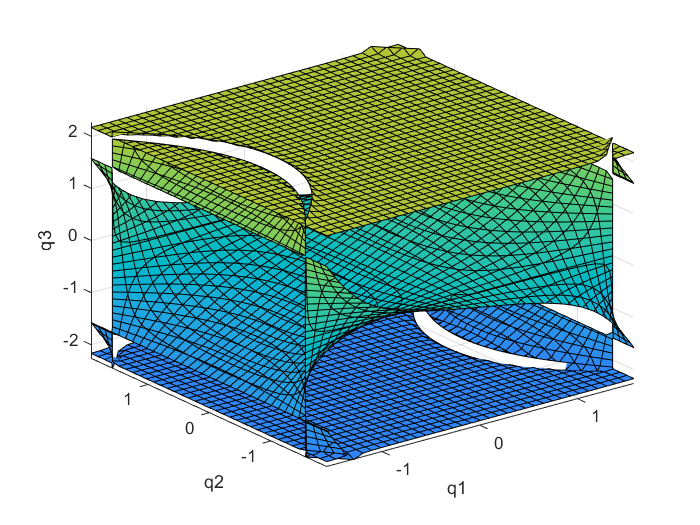

fimplicit3(detJ)
xlim([-Con(1,1)/2 Con(1,1)/2])
ylim([-Con(1,2)/2 Con(1,2)/2])
zlim([-Con(1,3)/2 Con(1,3)/2])
xlabel("q1")
ylabel("q2")
zlabel("q3")

## prova

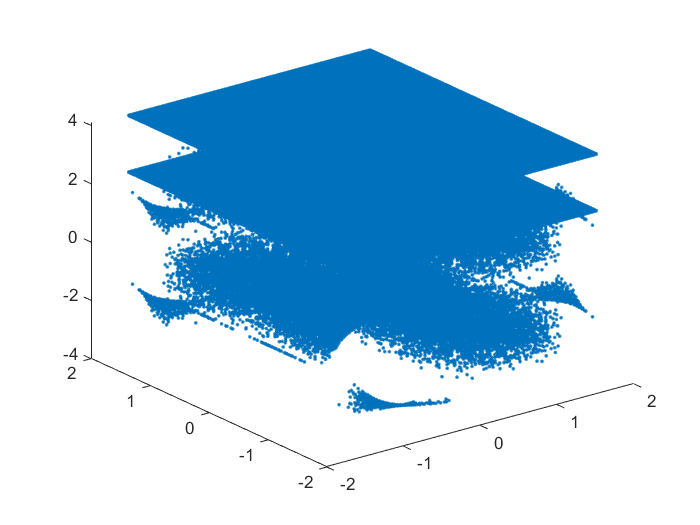

a=1000;
b=1000;
i=0;
realSol=NaN(3,a*b*4);
for q1 = linspace(-Con(1,1)/2,Con(1,1)/2,a)
    for q2 = linspace(-Con(1,2)/2,Con(1,2)/2,b)
        q3=eqn(q1,q2);
        for q=q3'
            if isreal(q)
                i=i+1;
                realSol(:,i)=[q1;q2;q];
            end
        end
        
    end
end
for i=1:a*b*4
    if(isnan(realSol(1,i)))
        length=i-1;
        break
    end
end
realSol=realSol(:,1:length);
plot3(realSol(1,:),realSol(2,:),realSol(3,:),'.')

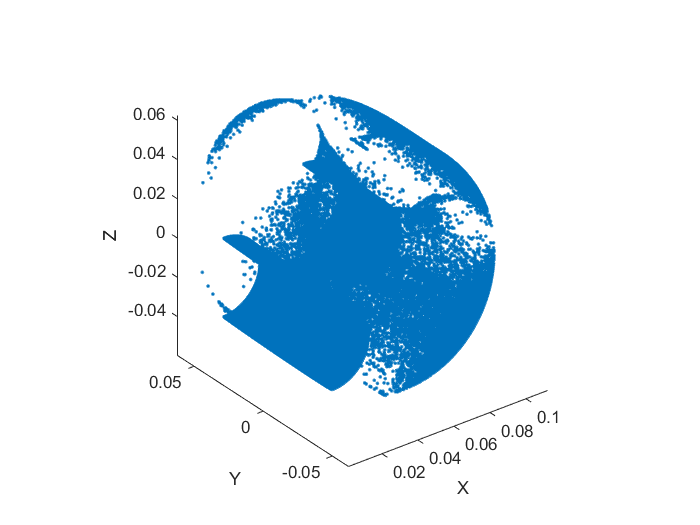

S=zeros(4,length);
for i=1:length
    S(:,i)=TR4_dirKin(realSol(:,i),link);
end
plot3(S(1,:),S(2,:),S(3,:),'.')
xlabel("X")
ylabel("Y")
zlabel("Z")
axis equal

## discretization pt1

div=150;
Xdiv=div;Ydiv=div;Zdiv=div;
xmax=max(S(1,:));
xmin=min(S(1,:));
ymax=max(S(2,:));
ymin=min(S(2,:));
zmax=max(S(3,:));
zmin=min(S(3,:));
X=linspace(xmin,xmax,Xdiv);
dx=X(2)-X(1);
Y=linspace(ymin,ymax,Ydiv);
dy=Y(2)-Y(1);
Z=linspace(zmin,zmax,Zdiv);
dz=Z(2)-Z(1);

## discretization pt2

space=zeros(Xdiv,Ydiv,Zdiv);
for p=S
    x=p(1);
    y=p(2);
    z=p(3);
    xinf=find(X<=x);
    xinf=xinf(end);
    yinf=find(Y<=y);
    yinf=yinf(end);
    zinf=find(Z<=z);
    zinf=zinf(end);
    space(xinf,yinf,zinf)=1;
end

## plot results

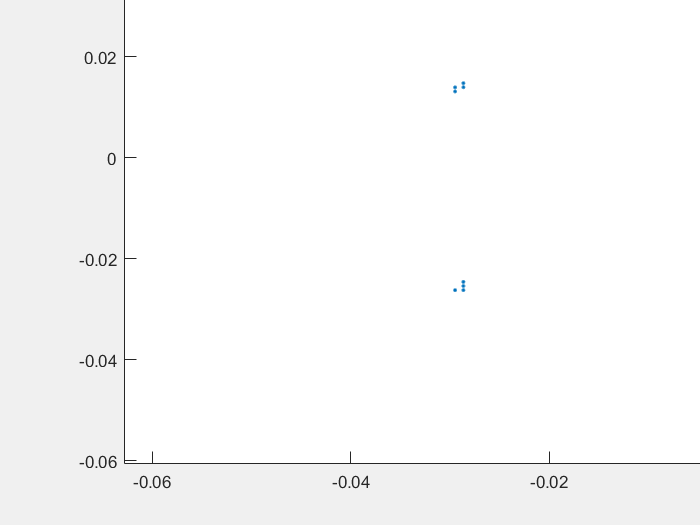

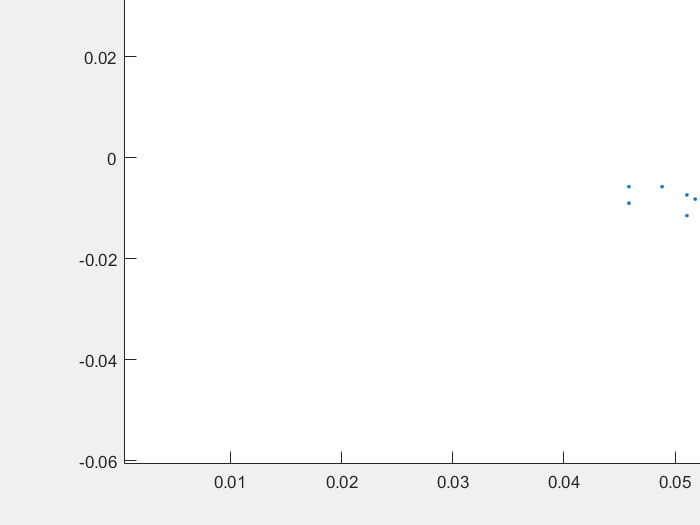

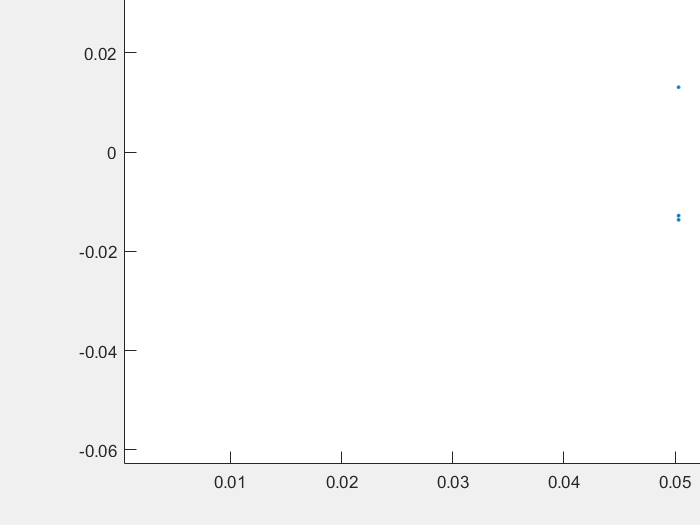

close all
clear all
load Singolarità_Cartesiane.mat
sliderX(space,Xdiv,X,Y,Z)
sliderY(space,Ydiv,X,Y,Z)
sliderZ(space,Zdiv,X,Y,Z)

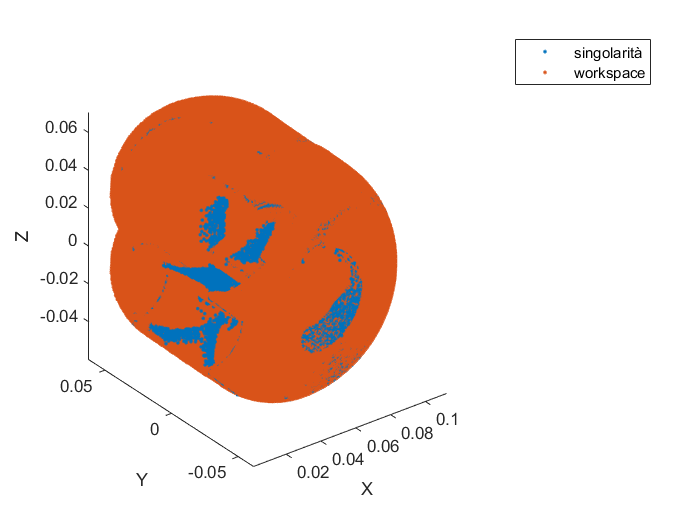

point2plot=nan(3,Xdiv*Ydiv*Zdiv);
point2plot_inner=nan(3,Xdiv*Ydiv*Zdiv);
p=1;
for i = 1:Xdiv
    for j = 1:Ydiv
        for k = 1:Zdiv
            if(space(i,j,k)==1)
                point2plot(:,p)=[X(i) Y(j) Z(k)]';
                p=p+1;
            end
        end
    end
end
figure
plot3(point2plot(1,:),point2plot(2,:),point2plot(3,:),'.')
axis equal
hold on
load TR4_ws_dv_constrain.mat
point2plot=nan(3,Xdiv*Ydiv*Zdiv);
point2plot_inner=nan(3,Xdiv*Ydiv*Zdiv);
p=1;
for i = 1:Xdiv
    for j = 1:Ydiv
        for k = 1:Zdiv
            if(space_(i,j,k)==1)
                point2plot(:,p)=[X(i) Y(j) Z(k)]';
                p=p+1;
            end
        end
    end
end
plot3(point2plot(1,:),point2plot(2,:),point2plot(3,:),'.')
axis equal
xlabel('X')
ylabel('Y')
zlabel('Z')
legend('singolarità','workspace')

## save

save Singolarità_Cartesiane S space X Xdiv Y Ydiv Z Zdiv